# Final Project - Walter and Yehya (QEAII Final)

## Midfoot Strike- Test #1

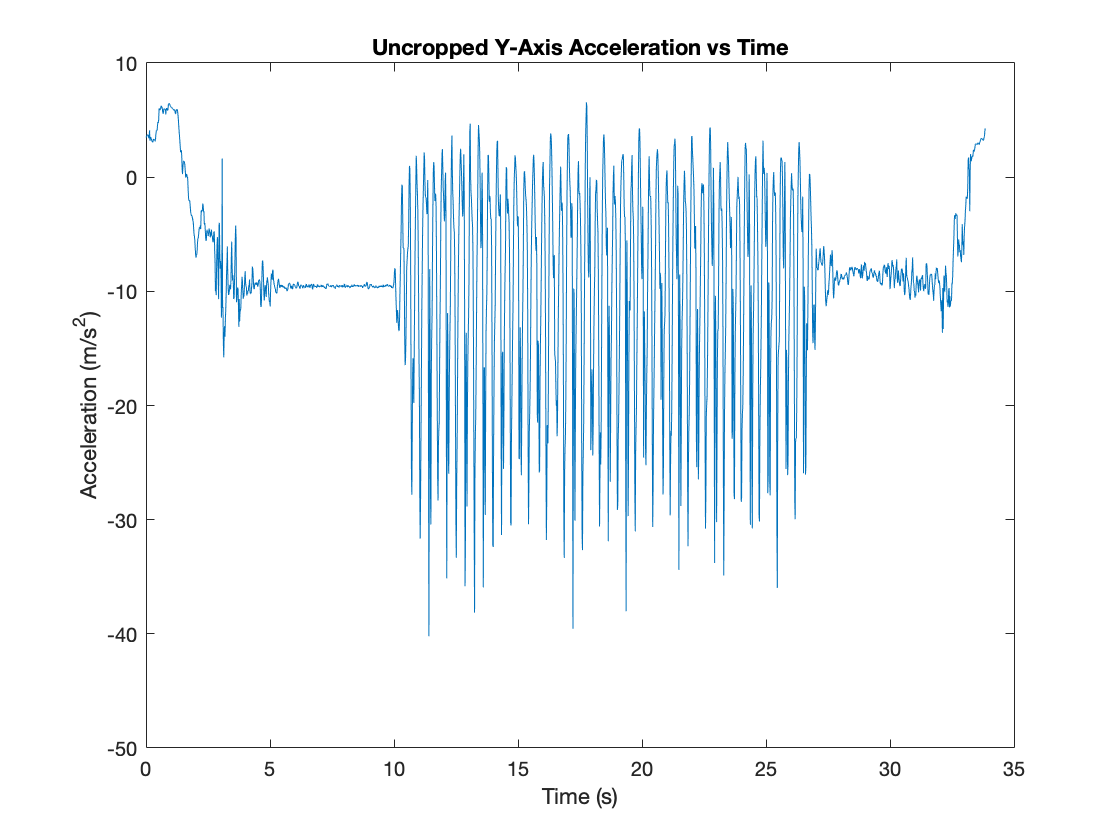

load midfootStep.mat
Acceleration;

midfoot_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
midfoot_timeInSeconds = seconds(midfoot_timeList - midfoot_timeList(1));
midfootAccel =  timetable2table(Acceleration);
midfoot_final = table2array(midfootAccel(:,2:4));
midfoot_q = midfoot_timeInSeconds;
midfoot_finalArray = [midfoot_q midfoot_final];

% Data in Array Format
midfoot_finalArray;


% midfoot_yaxis plotted - UNCROPPED;
plot(midfoot_finalArray(:,1), midfoot_finalArray(:,3));
title("Uncropped Y-Axis Acceleration vs Time")
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");

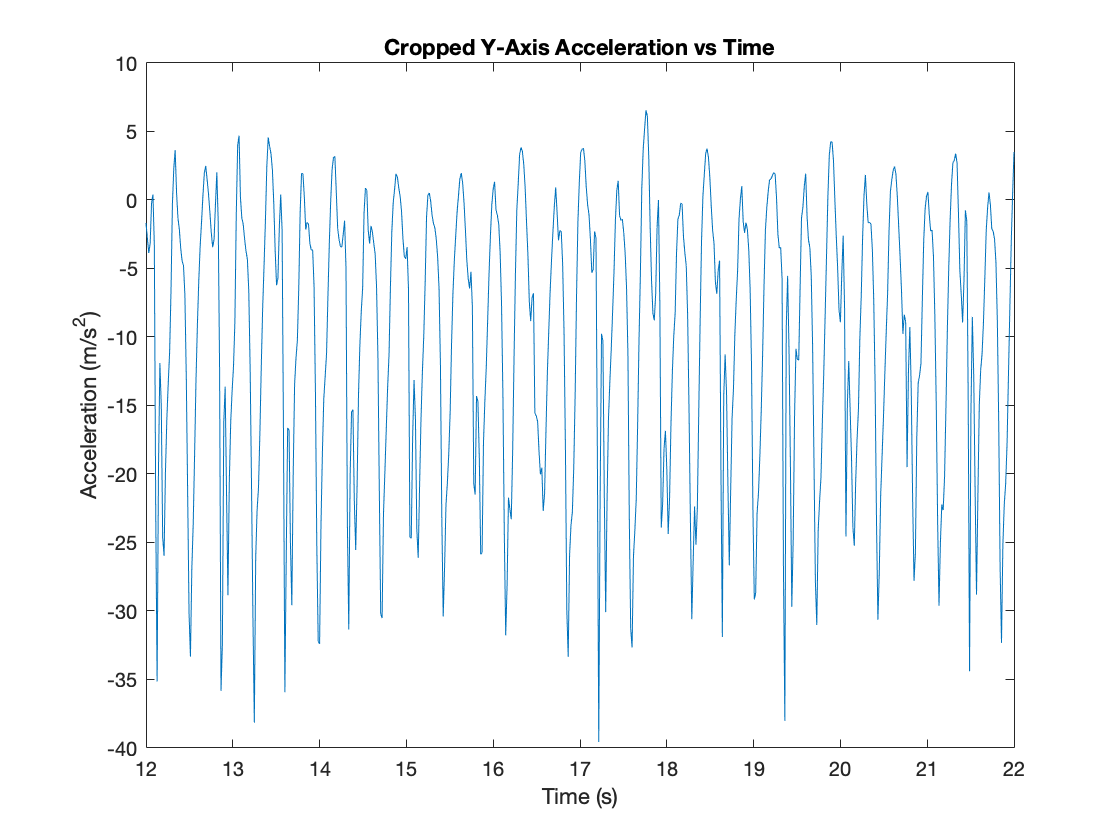



% Crop data at t = 12-22
% V = valid data that we can use
Vmidfoot_time_data = midfoot_finalArray(751:1376, 1);
Vmidfoot_xaxis_data = midfoot_finalArray(751:1376, 2);
Vmidfoot_yaxis_data = midfoot_finalArray(751:1376, 3);
Vmidfoot_zaxis_data = midfoot_finalArray(751:1376, 4);

% new array for midfootStep data
midfootStep_FINAL = [Vmidfoot_time_data Vmidfoot_xaxis_data Vmidfoot_yaxis_data Vmidfoot_zaxis_data]; % This is the data we are using

%---- New Cropped Data - PLOTS -----

%Cropped data for y-axis acceleration vs time
plot(midfootStep_FINAL(:,1), midfootStep_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");

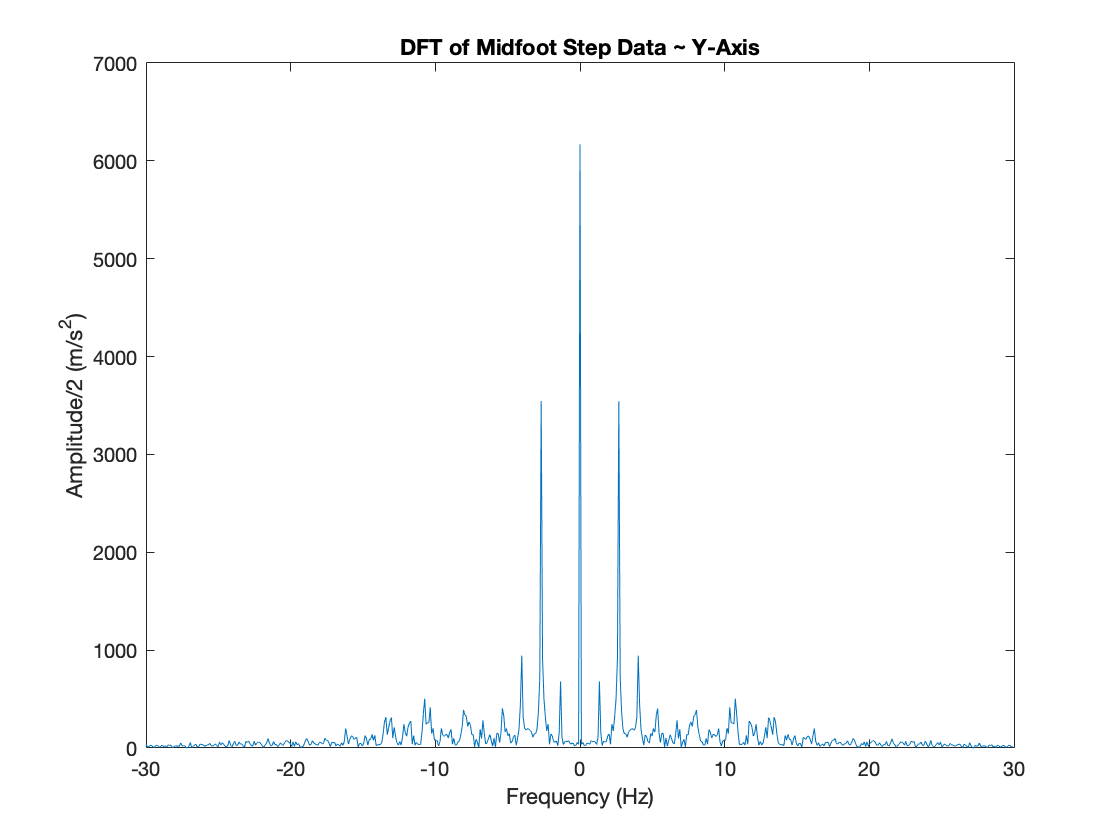



% Plotting the DFT for Y-Axis Acceleration %
P_mid = fftshift(fft(midfootStep_FINAL(:,3)));% FFT graph
Fs = 60; %sampling frequency (Hz)
N_mid = length(P_mid);
F_mid = (linspace(-pi, pi-2/N_mid*pi, N_mid) + pi/N_mid*mod(N_mid,2)) * Fs / (2 * pi); %Domain in Hertz - convert from rad/sec to Hz by dividing by 2*pi


% Plotting the DFT
plot(F_mid,abs(P_mid')) 
title("DFT of Midfoot Step Data ~ Y-Axis");
xlabel("Frequency (Hz)");
ylabel("Amplitude/2 (m/s^2)")

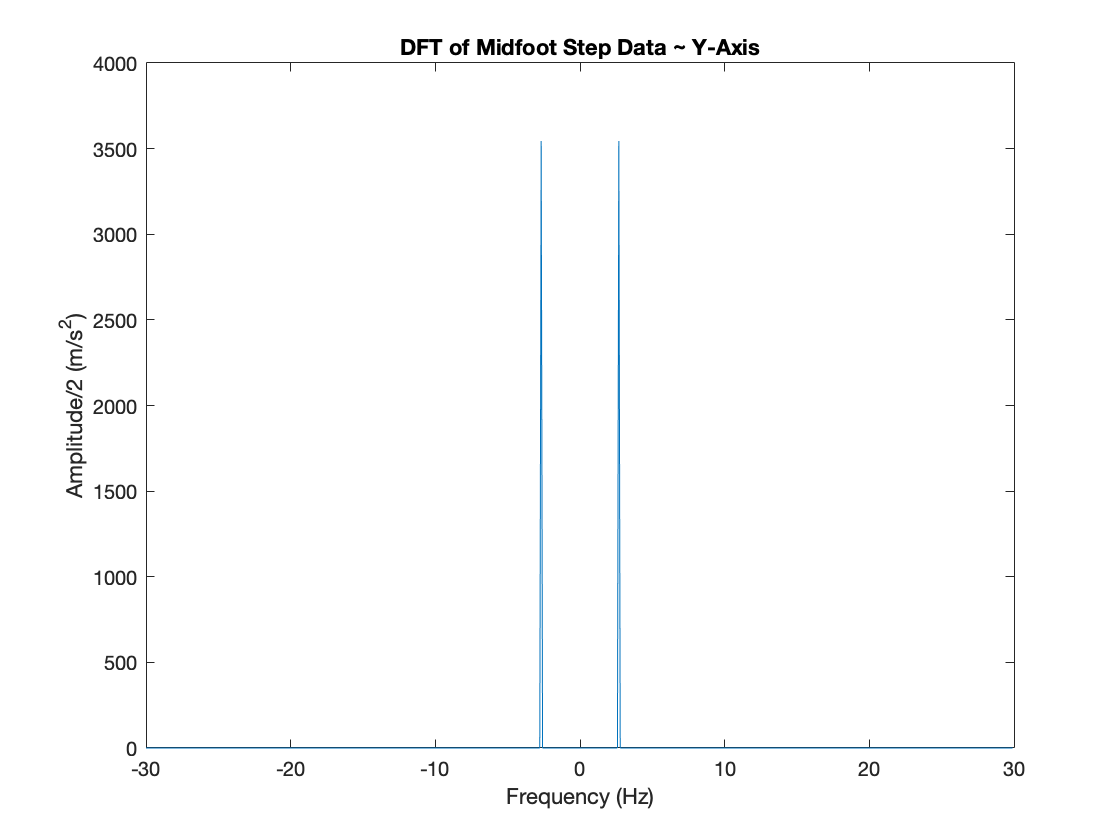


% Algorithm Used to Filter

idx_mid = F_mid == 0;   % Finding Idex of when F_mid = 0
P_mid(idx_mid) = 0;     % Setting the value at that index = 0
maxi = max(abs(P_mid)); % Setting the next highest peaks to the max

% Looping to identify the peaks in our DFT
idx_max = F_mid == maxi;
for i = 1:length(P_mid);
    if abs(P_mid(i)) < maxi;
        P_mid(i) = 0;
    end 
end

% Plotting only the highest peaks
plot(F_mid,abs(P_mid')) % Plotting the DFT
title("DFT of Midfoot Step Data ~ Y-Axis");
xlabel("Frequency (Hz)");
ylabel("Amplitude/2 (m/s^2)")

## Heel Step  - Test #1

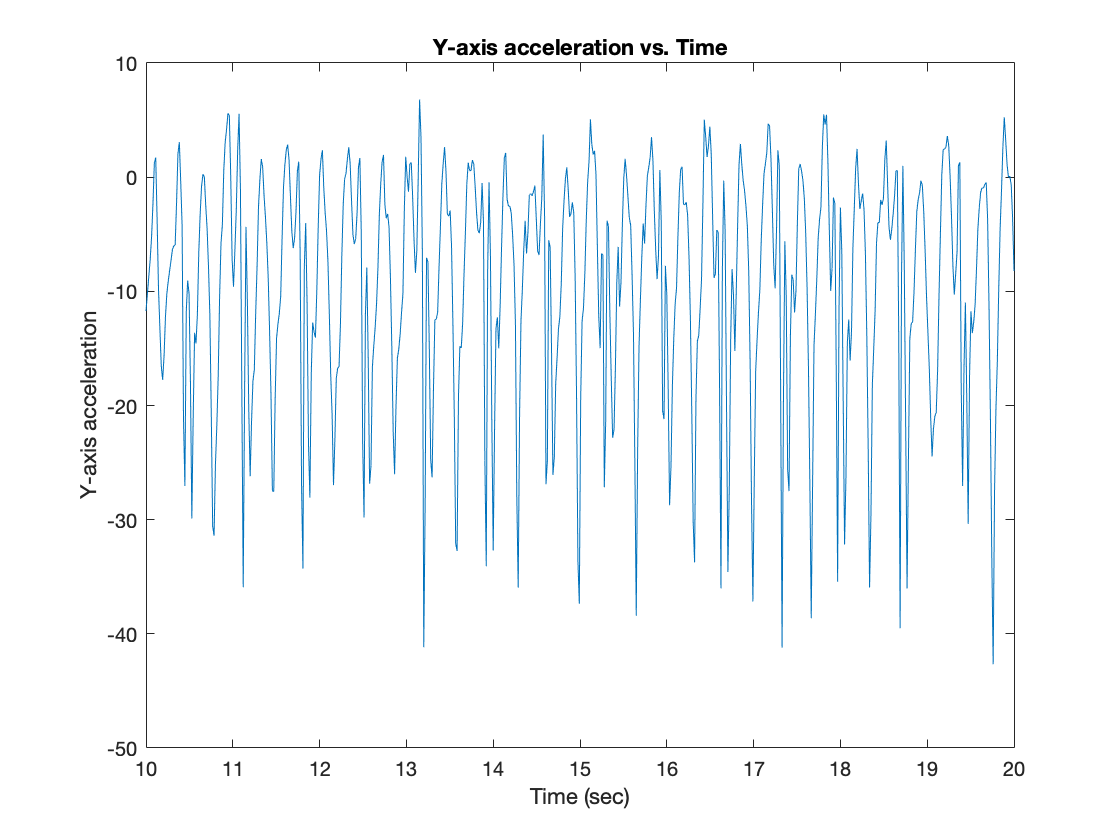

load heelStep.mat

Acceleration;

heelstep_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
heelstep_timeInSeconds = seconds(heelstep_timeList - heelstep_timeList(1));
heelStepAccel = timetable2table(Acceleration);
heelstep_final = table2array(heelStepAccel(:, 2:4));
heelstep_q = heelstep_timeInSeconds;
heelstep_finalArray = [heelstep_q heelstep_final];

% Data in Array Format
heelstep_finalArray;


% NEW DATA %
% Crop data at t = 10-20
% V = valid data that we can use
Vheelstep_time_data = heelstep_finalArray(626:1251, 1);
Vheelstep_xaxis_data = heelstep_finalArray(626:1251, 2);
Vheelstep_yaxis_data = heelstep_finalArray(626:1251, 3);
Vheelstep_zaxis_data = heelstep_finalArray(626:1251, 4);

% NEW ARRAY for heelStep data
heelStep_FINAL = [Vheelstep_time_data Vheelstep_xaxis_data Vheelstep_yaxis_data Vheelstep_zaxis_data]; % This is the data we are actually going to use

plot(heelStep_FINAL(:,1), heelStep_FINAL(:,3));
title("Y-axis acceleration vs. Time");
xlabel("Time (sec)");
ylabel("Y-axis acceleration")

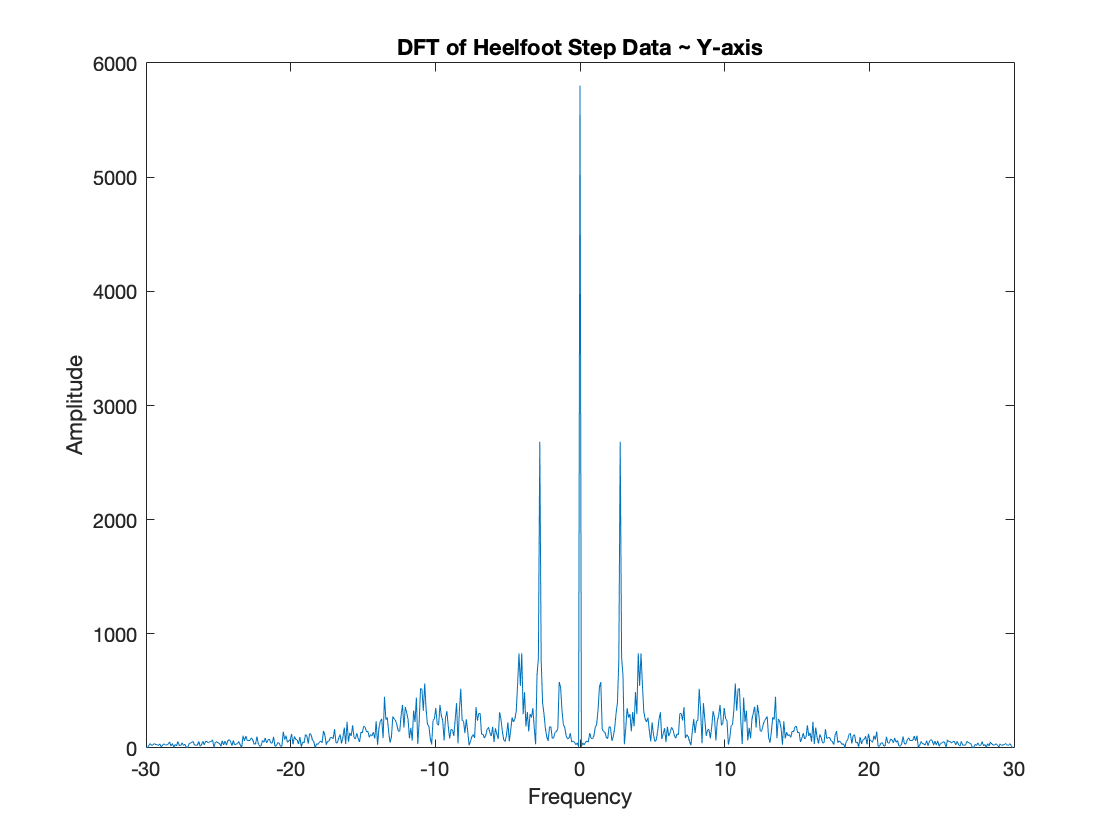



% Plotting the DFT for Y-Axis Acceleration %
P_heel = fftshift(fft(heelStep_FINAL(:,3))); %FFT Graph
Fs = 60; %sampling frequency (Hz)
N_heel = length(P_heel);
F_heel = (linspace(-pi, pi-2/N_heel*pi, N_heel) + pi/N_heel*mod(N_heel,2)) * Fs / (2 * pi); %Domain in Hertz converted from rad/sec by dividing by 2*pi%

% Plotting the DFT
plot(F_heel,abs(P_heel')) 
title("DFT of Heelfoot Step Data ~ Y-axis");
xlabel("Frequency");
ylabel("Amplitude")

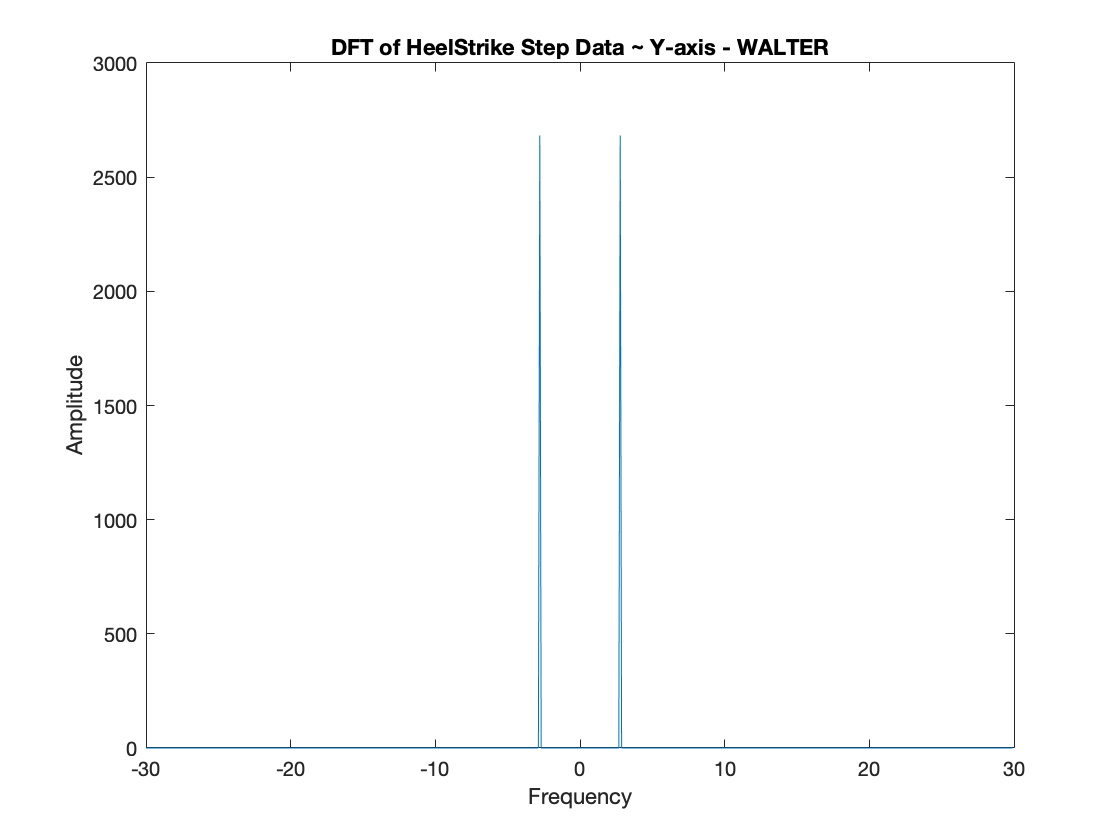



% Algorithm used to filter 

idx_heel = F_heel == 0;       % Finding Idex of when F_mid = 0
P_heel(idx_heel) = 0;         % Setting the value at that index = 0
maxi_heel = max(abs(P_heel)); % Setting the next highest peaks to the max


% Looping to identify the peaks in our DFT
idx_heel = F_heel == maxi_heel;
for i = 1:length(P_heel)
    if abs(P_heel(i)) < maxi_heel
        P_heel(i) = 0;
    end
end

% Plotting the DFT
plot(F_heel,abs(P_heel')) 
title("DFT of HeelStrike Step Data ~ Y-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");

## Midfoot Strike - Test #2

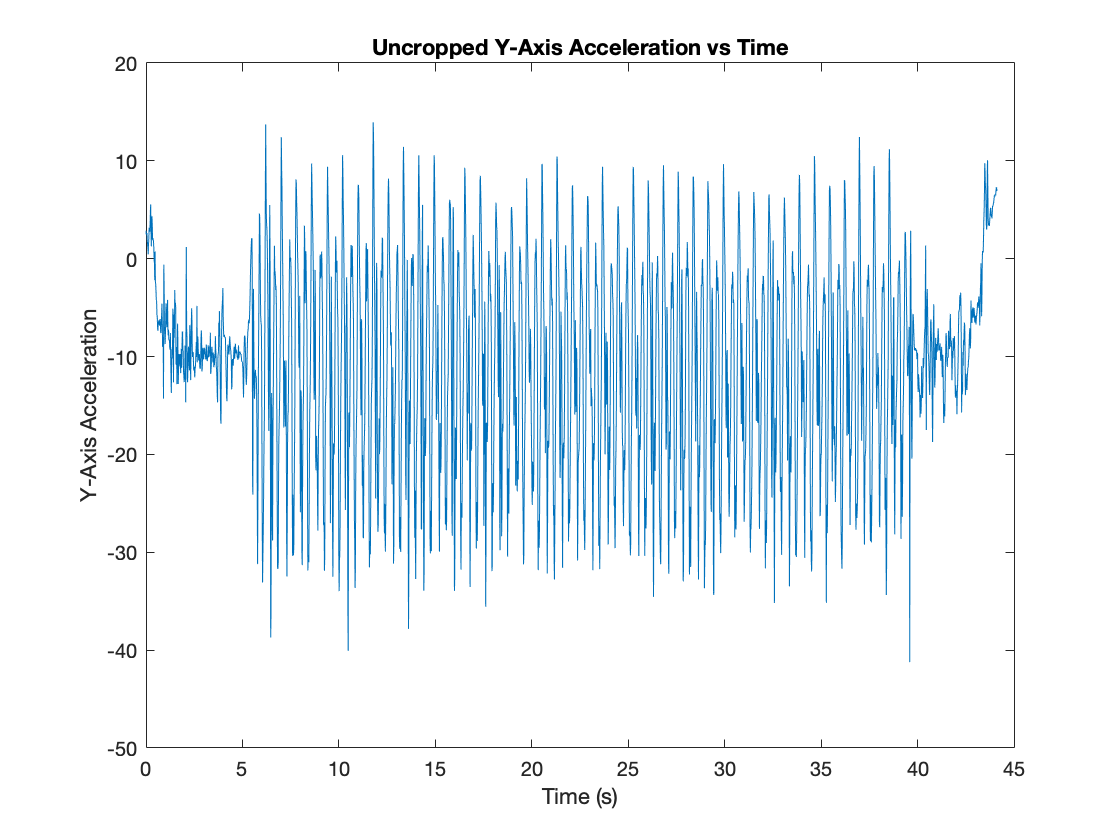

load midstrike_walter.mat
Acceleration;


midstrikeW_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
midstrikeW_timeInSeconds = seconds(midstrikeW_timeList - midstrikeW_timeList(1));
midstrikeW_Accel = timetable2table(Acceleration);
midstrikeW_final = table2array(midstrikeW_Accel(:,2:4));
midstrikeW_q = midstrikeW_timeInSeconds;
midstrikeW_finalArray = [midstrikeW_q midstrikeW_final];

% Data in Array Format
midstrikeW_finalArray;


% midstrikeW_yaxis;
plot(midstrikeW_finalArray(:,1), midstrikeW_finalArray(:,3));
title("Uncropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

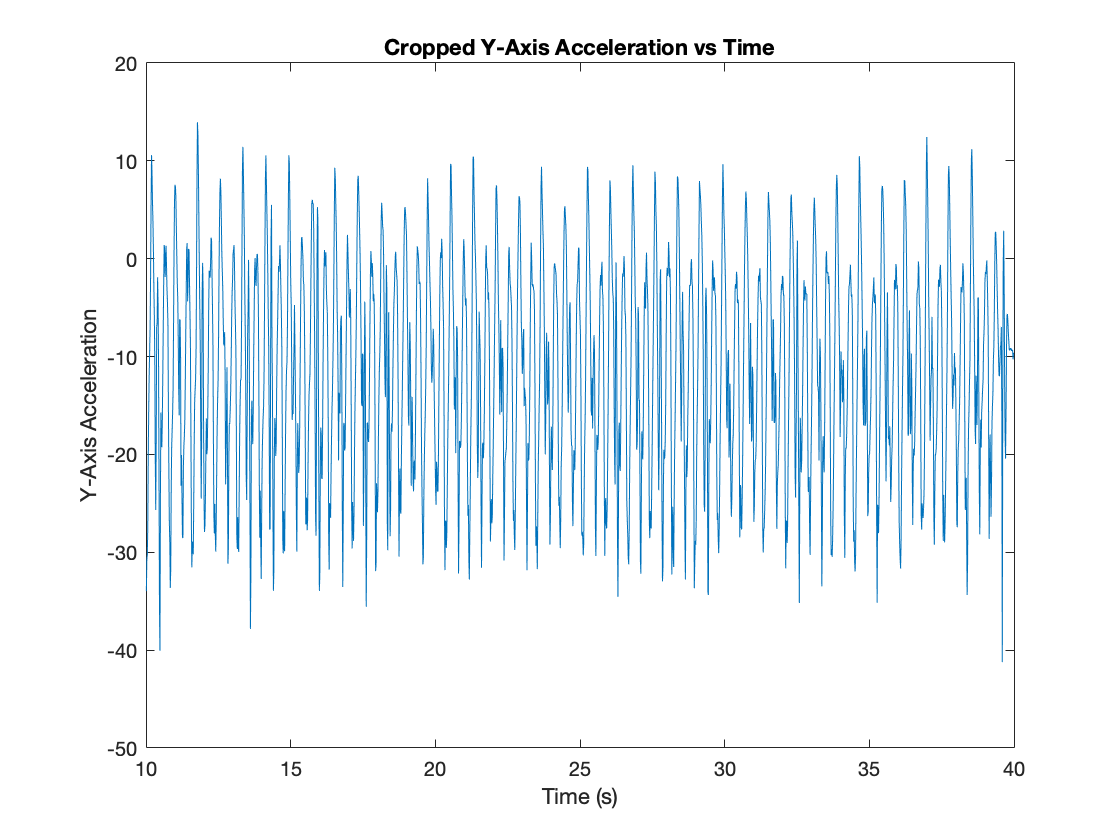


 
% Crop data at t = 10.0130 - 40
% V = valid data that we can use
VmidstrikeW_time_data = midstrikeW_finalArray(619:2470, 1);
VmidstrikeW_xaxis_data = midstrikeW_finalArray(619:2470, 2);
VmidstrikeW_yaxis_data = midstrikeW_finalArray(619:2470, 3);
VmidstrikeW_zaxis_data = midstrikeW_finalArray(619:2470, 4);

% new array for midfootStep data
midstrikeW_FINAL = [VmidstrikeW_time_data VmidstrikeW_xaxis_data VmidstrikeW_yaxis_data VmidstrikeW_zaxis_data]; % This is the data we are using

%---- New Cropped WALTER Data - PLOTS -----
     
%Cropped data for y-axis acceleration vs time
plot(midstrikeW_FINAL(:,1), midstrikeW_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

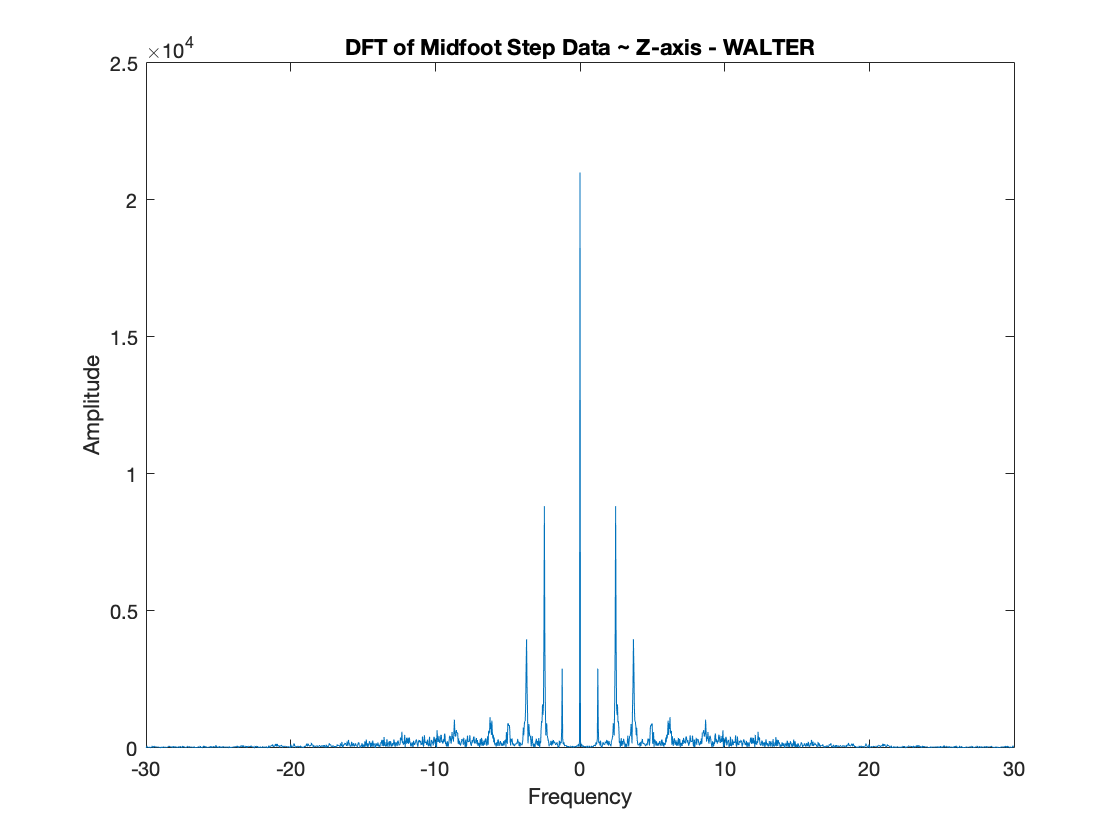



% Plotting the DFT for Y-Axis Acceleration %
P_midstrikeW = fftshift(fft(midstrikeW_FINAL(:,3))); 
Fs = 60; %sampling frequency (Hz)
N_midstrikeW = length(P_midstrikeW);
F_midstrikeW = (linspace(-pi, pi-2/N_midstrikeW*pi, N_midstrikeW) + pi/N_midstrikeW*mod(N_midstrikeW,2))* Fs / (2 * pi); %Domain in Hertz%

% Plotting the DFT
plot(F_midstrikeW,abs(P_midstrikeW')) 
title("DFT of Midfoot Step Data ~ Z-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");

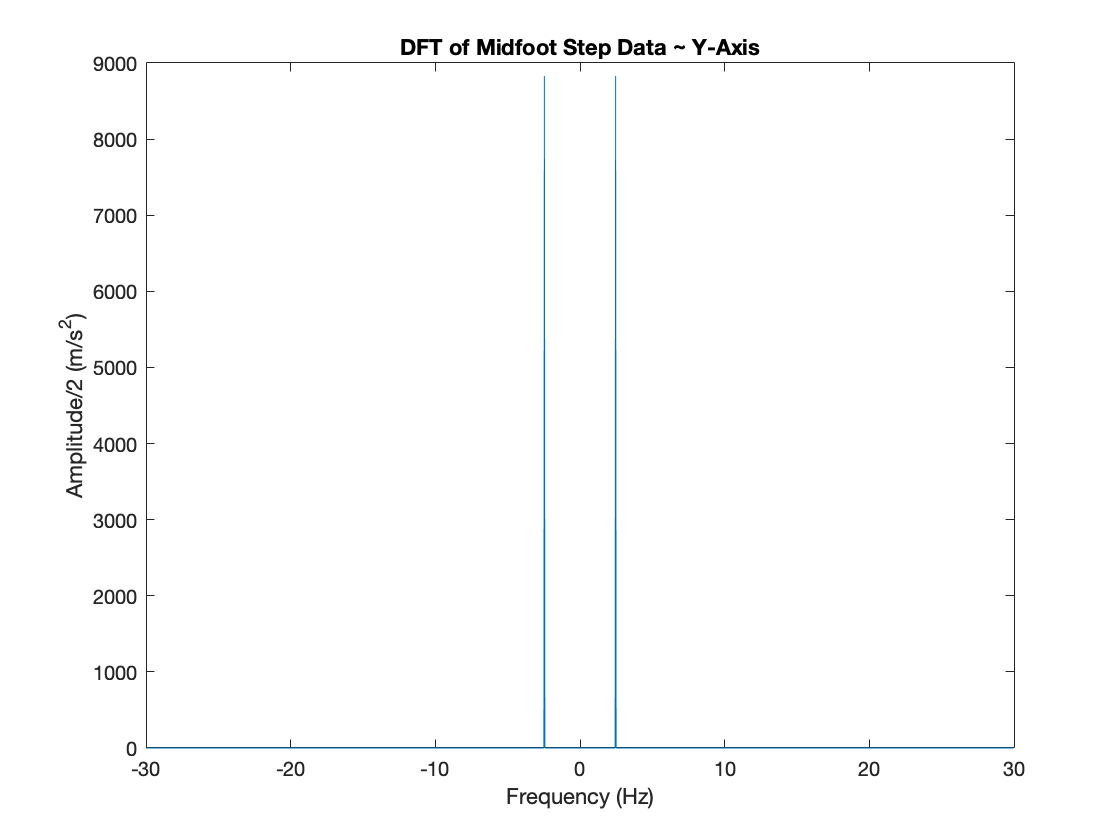



% Algorithm Used to Filter

idx_midW = F_midstrikeW == 0;   % Finding Idex of when F_mid = 0
P_midstrikeW(idx_midW) = 0;     % Setting the value at that index = 0
maxi_mW = max(abs(P_midstrikeW)); % Setting the next highest peaks to the max

% Looping to identify the peaks in our DFT
idx_maxW = F_midstrikeW == maxi_mW;
for i = 1:length(P_midstrikeW)
    if abs(P_midstrikeW(i)) < maxi_mW
        P_midstrikeW(i) = 0;
    end 
end

% Plotting only the highest peaks
plot(F_midstrikeW,abs(P_midstrikeW')) % Plotting the DFT
title("DFT of Midfoot Step Data ~ Y-Axis");
xlabel("Frequency (Hz)");
ylabel("Amplitude/2 (m/s^2)")

## Heelstrike - Test #2

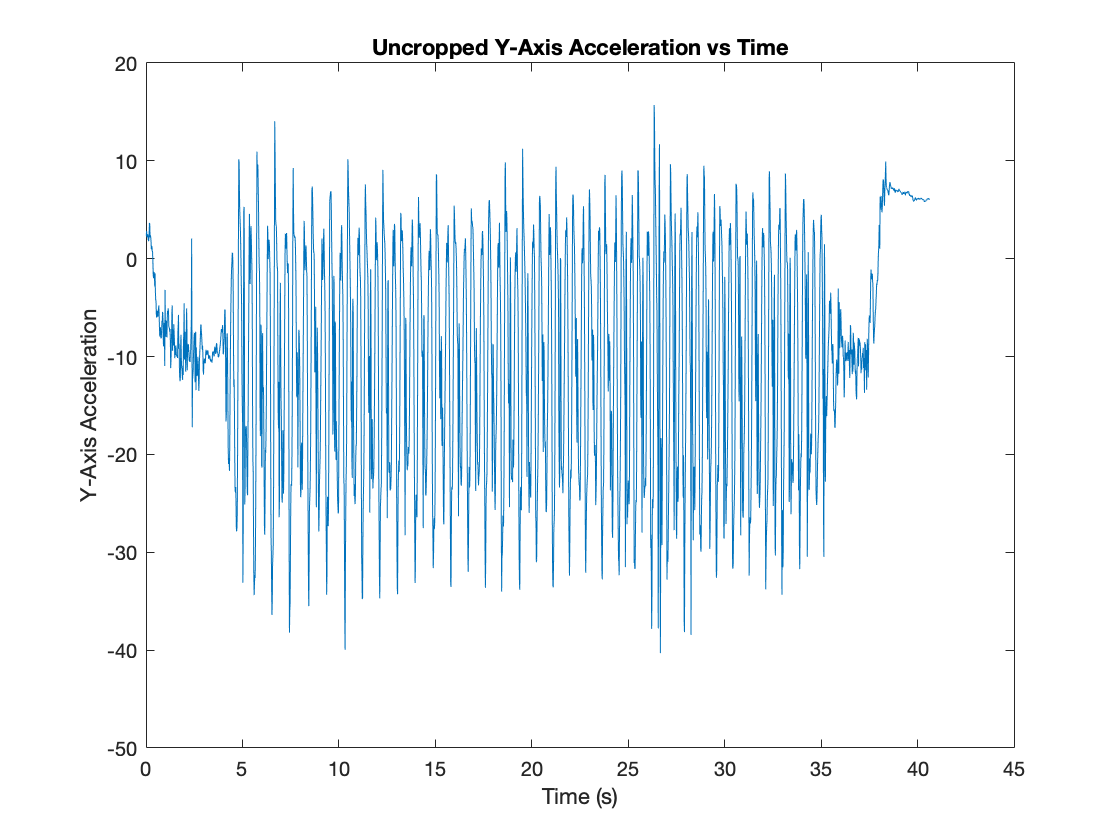

load heelstrike_walter.mat
Acceleration;

heelstrikeW_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
heelstrikeW_timeInSeconds = seconds(heelstrikeW_timeList - heelstrikeW_timeList(1));
heelstrikeW_Accel = timetable2table(Acceleration);
heelstrikeW_final = table2array(heelstrikeW_Accel(:,2:4));
heelstrikeW_q = heelstrikeW_timeInSeconds;
heelstrikeW_finalArray = [heelstrikeW_q heelstrikeW_final];

% Data in Array Format
heelstrikeW_finalArray; 


% heelstrikeW_yaxis;
plot(heelstrikeW_finalArray(:,1), heelstrikeW_finalArray(:,3));
title("Uncropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

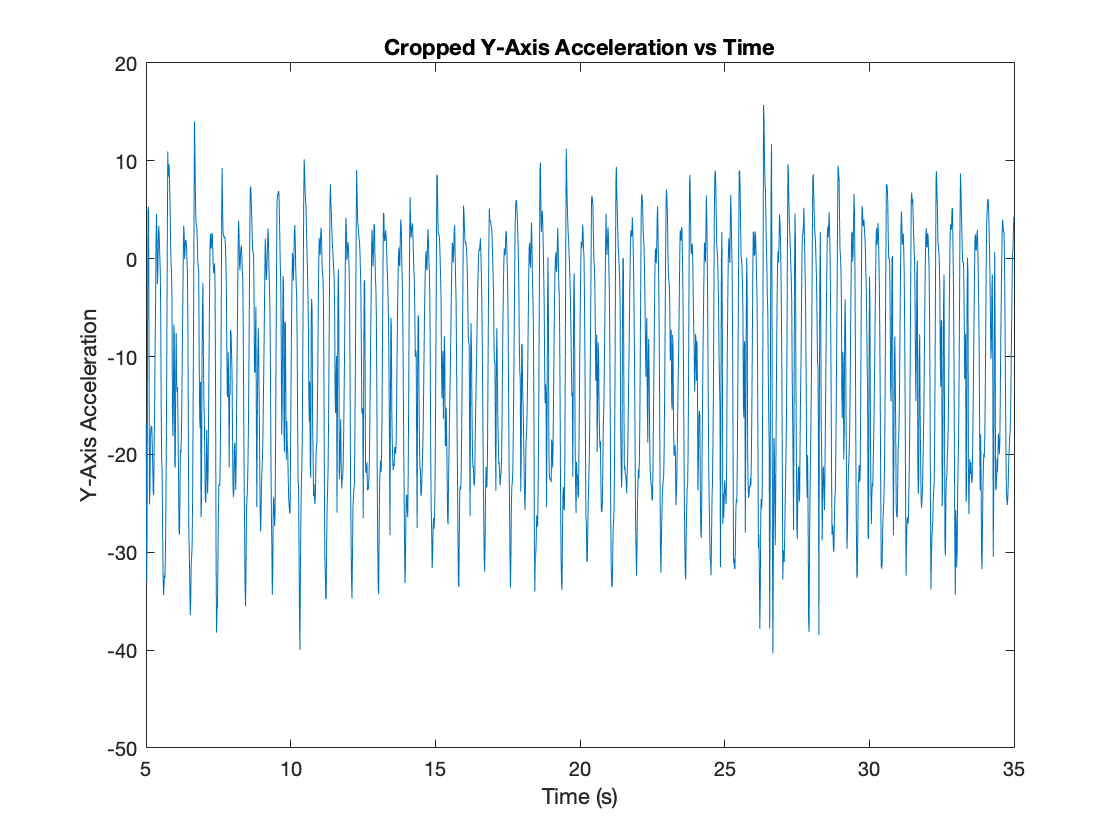


 
% Crop data at t = 5.0070 - 35.0120
% V = valid data that we can use
VheelstrikeW_time_data = heelstrikeW_finalArray(310:2161, 1);
VheelstrikeW_xaxis_data = heelstrikeW_finalArray(310:2161, 2);
VheelstrikeW_yaxis_data = heelstrikeW_finalArray(310:2161, 3);
VheelstrikeW_zaxis_data = heelstrikeW_finalArray(310:2161, 4);

% new array for midfootStep data
heelstrikeW_FINAL = [VheelstrikeW_time_data VheelstrikeW_xaxis_data VheelstrikeW_yaxis_data VheelstrikeW_zaxis_data]; % This is the data that we are going to use 
 
%---- New Cropped WALTER Data - PLOTS -----
        
%Cropped data for y-axis acceleration vs time
plot(heelstrikeW_FINAL(:,1), heelstrikeW_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

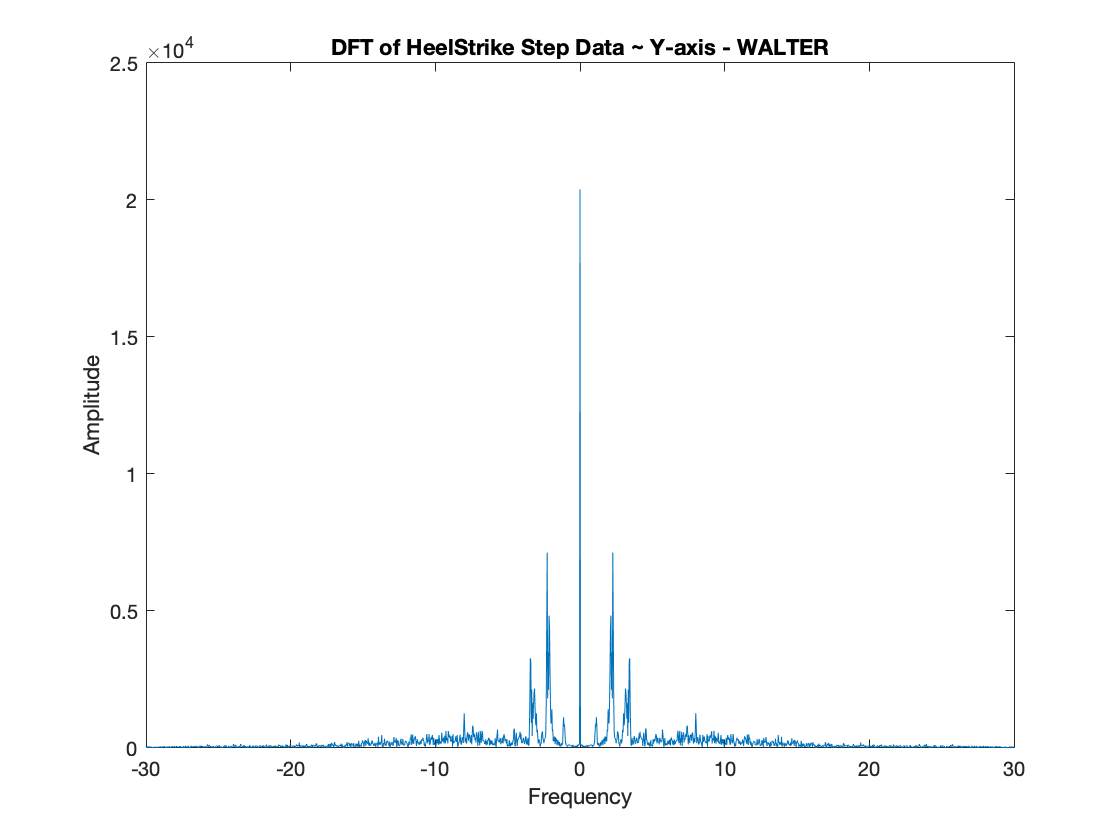



% Plotting the DFT for Y-Axis Acceleration %
P_heelstrikeW = fftshift(fft(heelstrikeW_FINAL(:,3)));
Fs = 60; %sampling frequency (Hz)
N_heelstrikeW = length(P_heelstrikeW);
F_heelstrikeW = (linspace(-pi, pi-2/N_heelstrikeW*pi, N_heelstrikeW) + pi/N_heelstrikeW*mod(N_heelstrikeW,2))* Fs / (2 * pi); %Domain in Hertz converted from rad/sec by dividing by 2*pi%


plot(F_heelstrikeW,abs(P_heelstrikeW')) % Plotting the DFT
title("DFT of HeelStrike Step Data ~ Y-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");



% Algorithm used to filter 

idx_heelW = F_heelstrikeW == 0;       % Finding Idex of when F_mid = 0
P_heelW(idx_heelW) = 0;                 % Setting the value at that index = 0
maxi_heelW = max(abs(P_heelW));         % Setting the next highest peaks to the max


% Looping to identify the peaks in our DFT
idx_heelW = F_heelstrikeW == maxi_heelW;
for i = 1:length(P_heelW)
    if abs(P_heelstrikeW(i)) < maxi_heelW
        P_heelstrikeW(i) = 0;
    end
end

% Plotting the DFT
plot(F_heelstrikeW,abs(P_heelstrikeW')) 
title("DFT of HeelStrike Step Data ~ Y-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");

## Midfoot Strike - Test #3

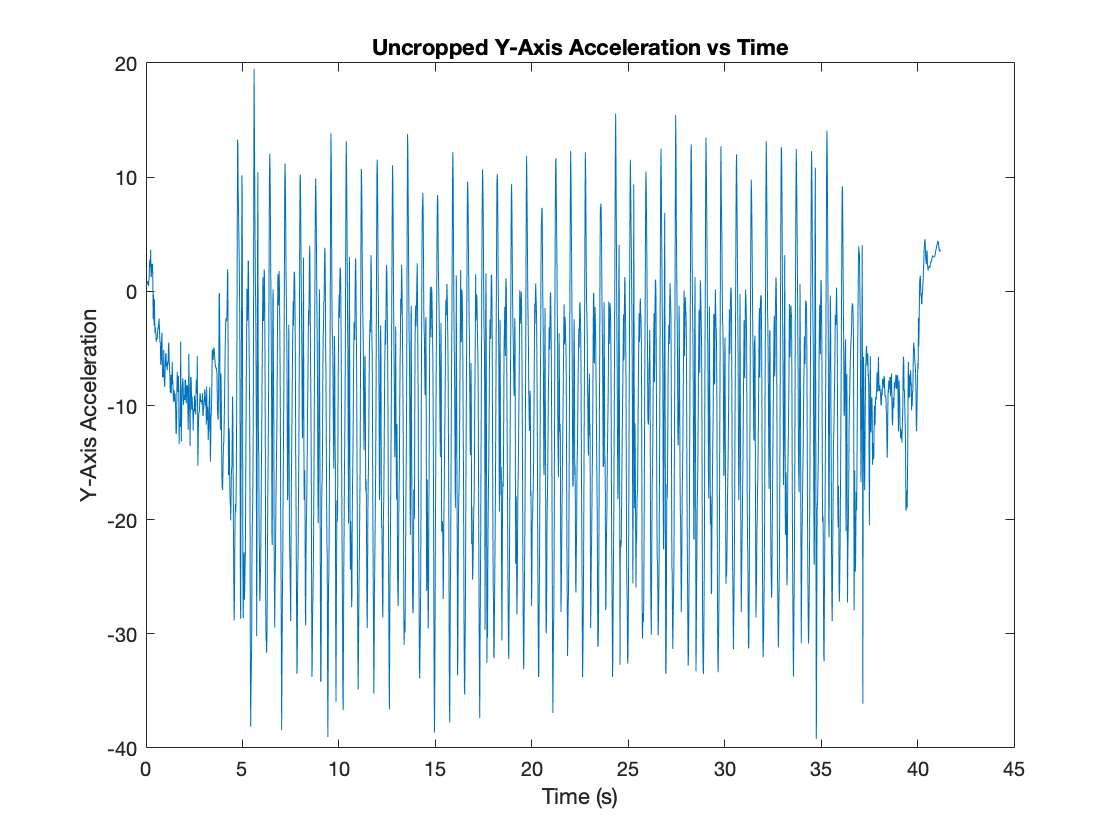

load LASTmidstrike_walter.mat;

Acceleration;

FINALmidstrike_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
FINALmidstrike_timeInSeconds = seconds(FINALmidstrike_timeList - FINALmidstrike_timeList(1));
FINALmidstrike_Accel = timetable2table(Acceleration);
FINALmidstrike_final = table2array(FINALmidstrike_Accel(:,2:4));
FINALmidstrike_q = FINALmidstrike_timeInSeconds;
FINALmidstrike_finalArray = [FINALmidstrike_q FINALmidstrike_final];

% Data in Array Format
FINALmidstrike_finalArray; 

 
% FINALmidstrike_yaxis;
plot(FINALmidstrike_finalArray(:,1), FINALmidstrike_finalArray(:,3));
title("Uncropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

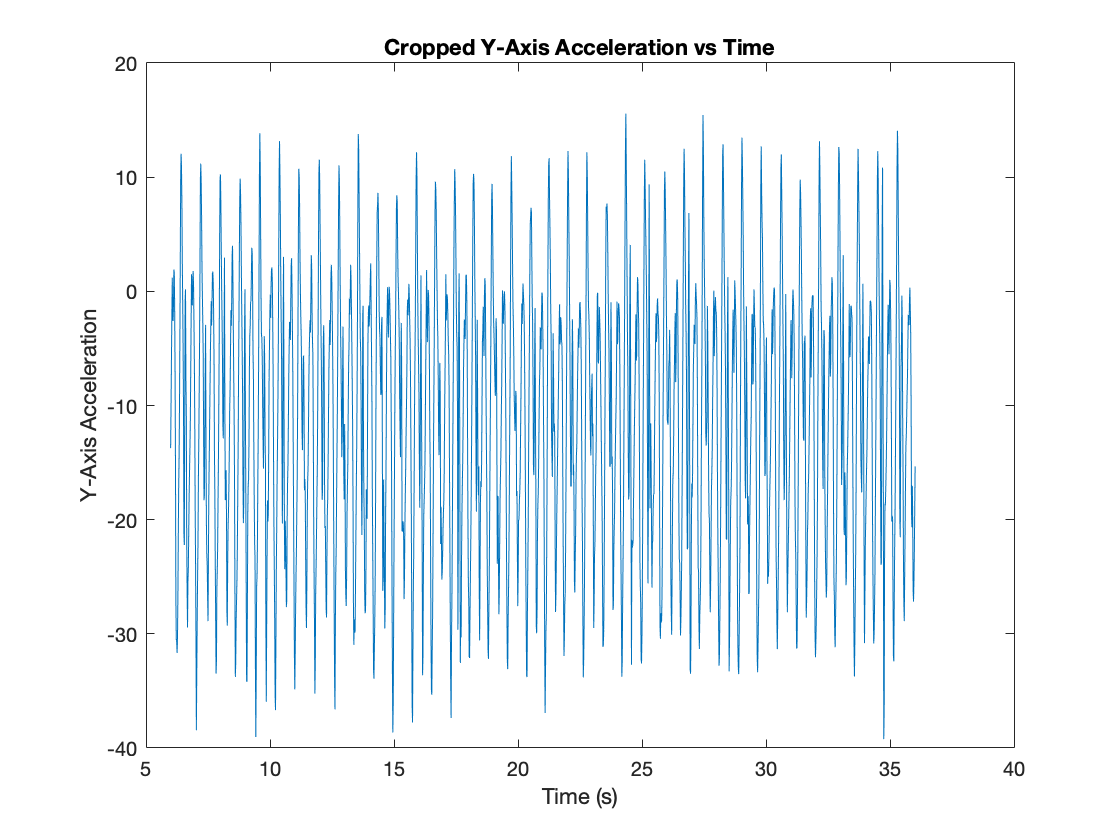


 

% Crop data at t = 5.99 (almost 6) - 36.0130
% V = valid data that we can use
VFINALmidstrike_time_data = FINALmidstrike_finalArray(371:2224, 1);
VFINALmidstrike_xaxis_data = FINALmidstrike_finalArray(371:2224, 2);
VFINALmidstrike_yaxis_data = FINALmidstrike_finalArray(371:2224, 3);
VFINALmidstrike_zaxis_data = FINALmidstrike_finalArray(371:2224, 4);

% new array for midfootStep data
FINALmidstrike_FINAL = [VFINALmidstrike_time_data VFINALmidstrike_xaxis_data VFINALmidstrike_yaxis_data VFINALmidstrike_zaxis_data]; % This is the data that we are using

% %---- New Cropped WALTER Data - PLOTS -----
        

%Cropped data for y-axis acceleration vs time
plot(FINALmidstrike_FINAL(:,1), FINALmidstrike_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

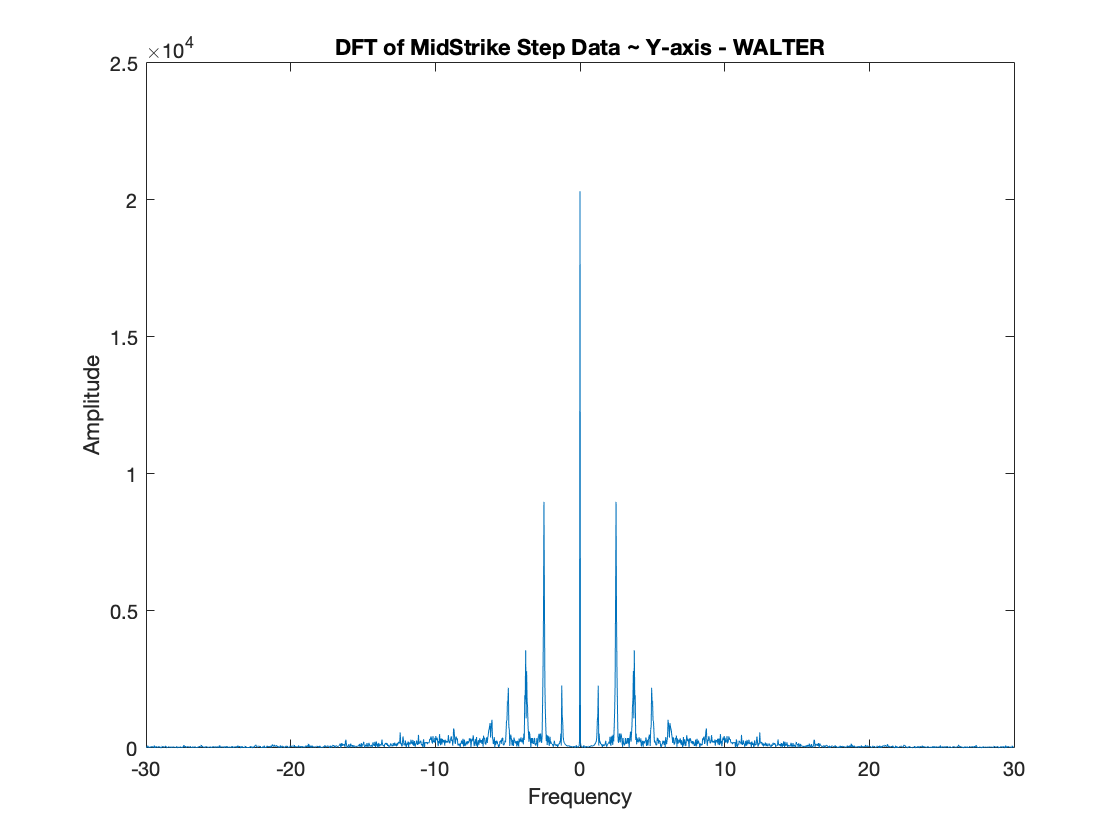



% Plotting the DFT for Y-Axis Acceleration %
P_FINALmidstrike = fftshift(fft(FINALmidstrike_FINAL(:,3))); %FFT Graph
Fs = 60; %sampling frequency (Hz)
N_FINALmidstrike = length(P_FINALmidstrike);
F_FINALmidstrike = (linspace(-pi, pi-2/N_FINALmidstrike*pi, N_FINALmidstrike) + pi/N_FINALmidstrike*mod(N_FINALmidstrike,2))* Fs / (2 * pi); %Domain in Hertz%


plot(F_FINALmidstrike,abs(P_FINALmidstrike')) % Plotting the DFT
title("DFT of MidStrike Step Data ~ Y-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");

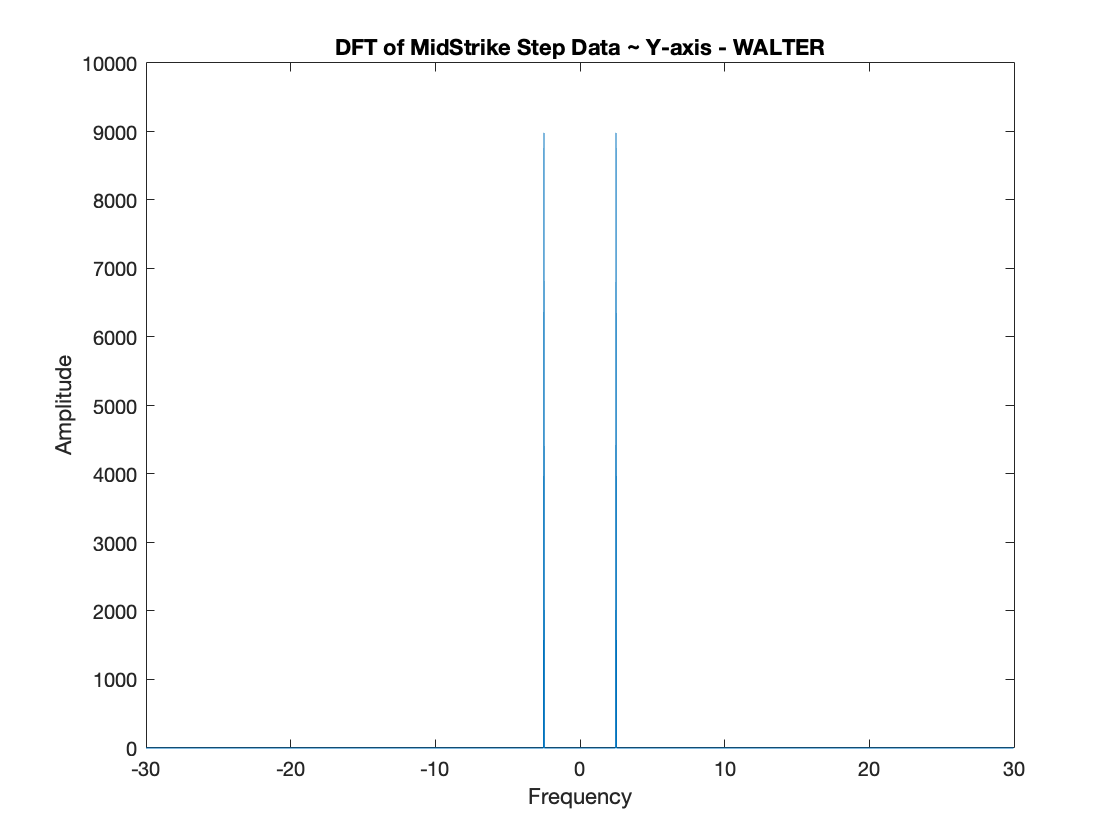



% Algorithm used to filter 
idx_mid = F_FINALmidstrike == 0;   % Finding Idex of when F_mid = 0
P_FINALmidstrike(idx_mid) = 0;     % Setting the value at that index = 0
maxi = max(abs(P_FINALmidstrike)); % Setting the next highest peaks to the max

% Looping to identify the peaks in our DFT
idx_max = F_FINALmidstrike == maxi;
for i = 1:length(P_FINALmidstrike)
    if abs(P_FINALmidstrike(i)) < maxi
        P_FINALmidstrike(i) = 0;
    end
end

plot(F_FINALmidstrike,abs(P_FINALmidstrike')) % Plotting the DFT
title("DFT of MidStrike Step Data ~ Y-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");
ylim([0 10000])

## Heel Strike - Test #3

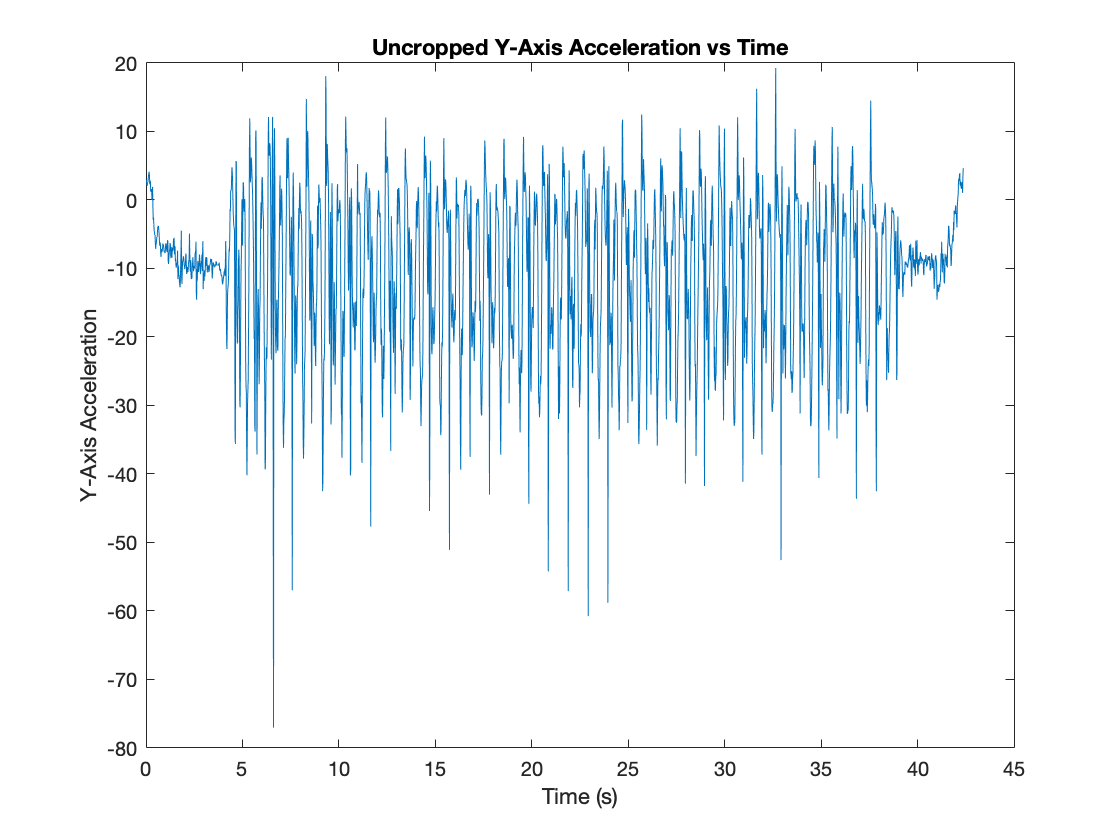

load LASTheelstrike_walter.mat;

Acceleration;

FINALheelstrike_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
FINALheelstrike_timeInSeconds = seconds(FINALheelstrike_timeList - FINALheelstrike_timeList(1));
FINALheelstrike_Accel = timetable2table(Acceleration);
FINALheelstrike_final = table2array(FINALheelstrike_Accel(:,2:4));
FINALheelstrike_q = FINALheelstrike_timeInSeconds;
FINALheelstrike_finalArray = [FINALheelstrike_q FINALheelstrike_final];

% Data in Array Format
FINALheelstrike_finalArray; 

% FINALheelstrike_yaxis;
plot(FINALheelstrike_finalArray(:,1), FINALheelstrike_finalArray(:,3));
title("Uncropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

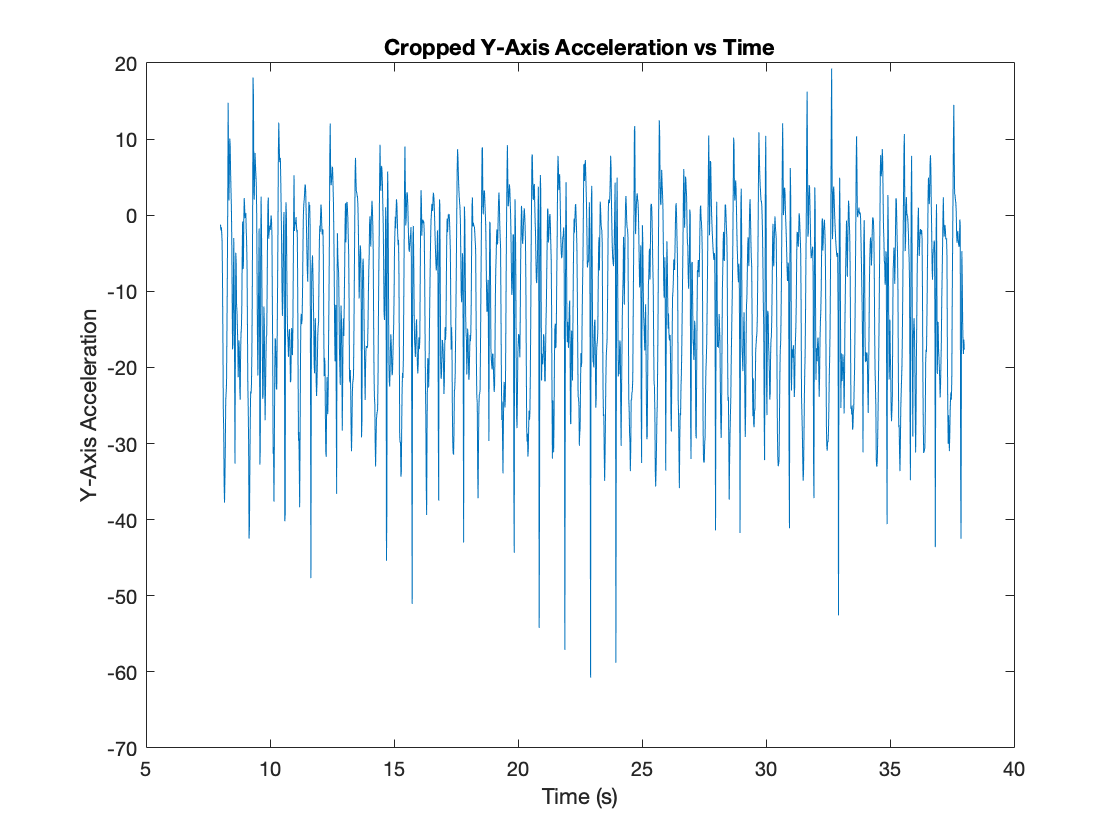



% Crop data at t = 8.004 - 38.01
% V = valid data that we can use
VFINALheelstrike_time_data = FINALheelstrike_finalArray(495:2346, 1);
VFINALheelstrike_xaxis_data = FINALheelstrike_finalArray(495:2346, 2);
VFINALheelstrike_yaxis_data = FINALheelstrike_finalArray(495:2346, 3);
VFINALheelstrike_zaxis_data = FINALheelstrike_finalArray(495:2346, 4);

% new array for midfootStep data
FINALheelstrike_FINAL = [VFINALheelstrike_time_data VFINALheelstrike_xaxis_data VFINALheelstrike_yaxis_data VFINALheelstrike_zaxis_data]; % This is the data that we are using

% %---- New Cropped WALTER Data - PLOTS -----
        

%Cropped data for y-axis acceleration vs time
plot(FINALheelstrike_FINAL(:,1), FINALheelstrike_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

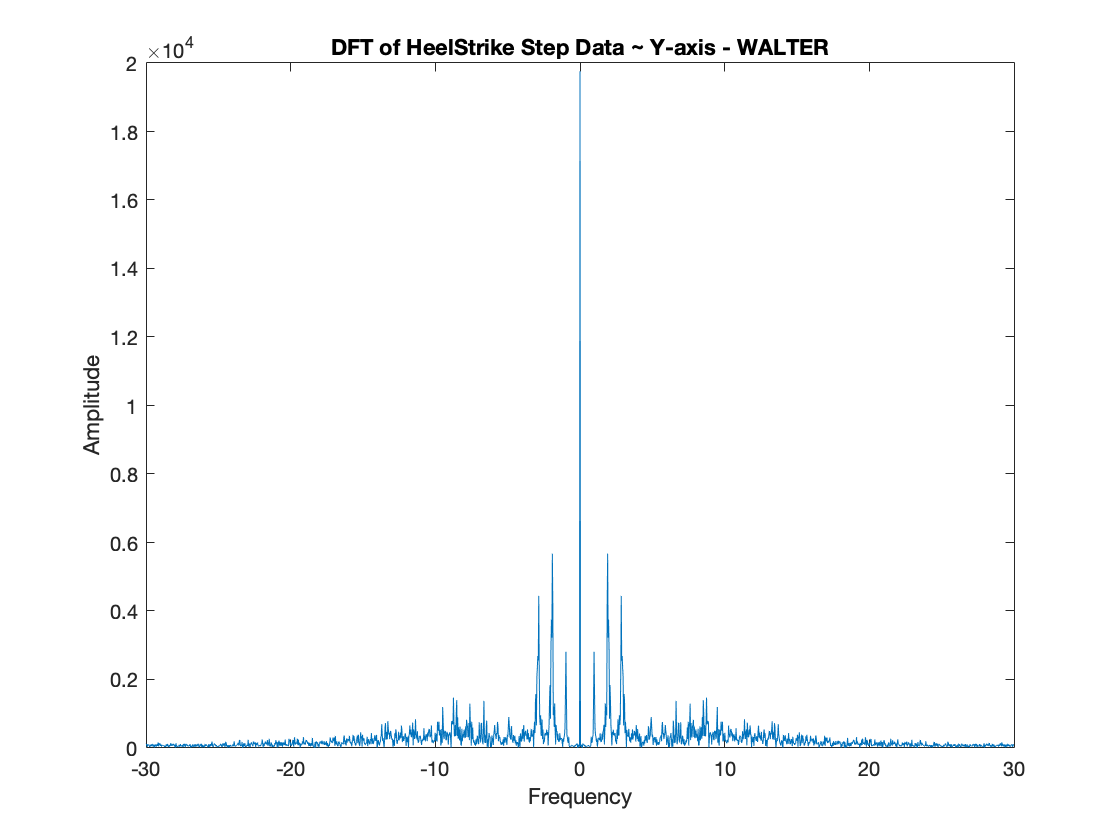



% Plotting the DFT for Y-Axis Acceleration %
P_FINALheelstrike = fftshift(fft(FINALheelstrike_FINAL(:,3))); % FFT Graph
Fs = 60; %sampling frequency (Hz)
N_FINALheelstrike = length(P_FINALheelstrike);
F_FINALheelstrike = (linspace(-pi, pi-2/N_FINALheelstrike*pi, N_FINALheelstrike) + pi/N_FINALheelstrike*mod(N_FINALheelstrike,2))* Fs / (2 * pi); %Domain in Hertz%


% Plotting the DFT
plot(F_FINALheelstrike,abs(P_FINALheelstrike')) 
title("DFT of HeelStrike Step Data ~ Y-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");

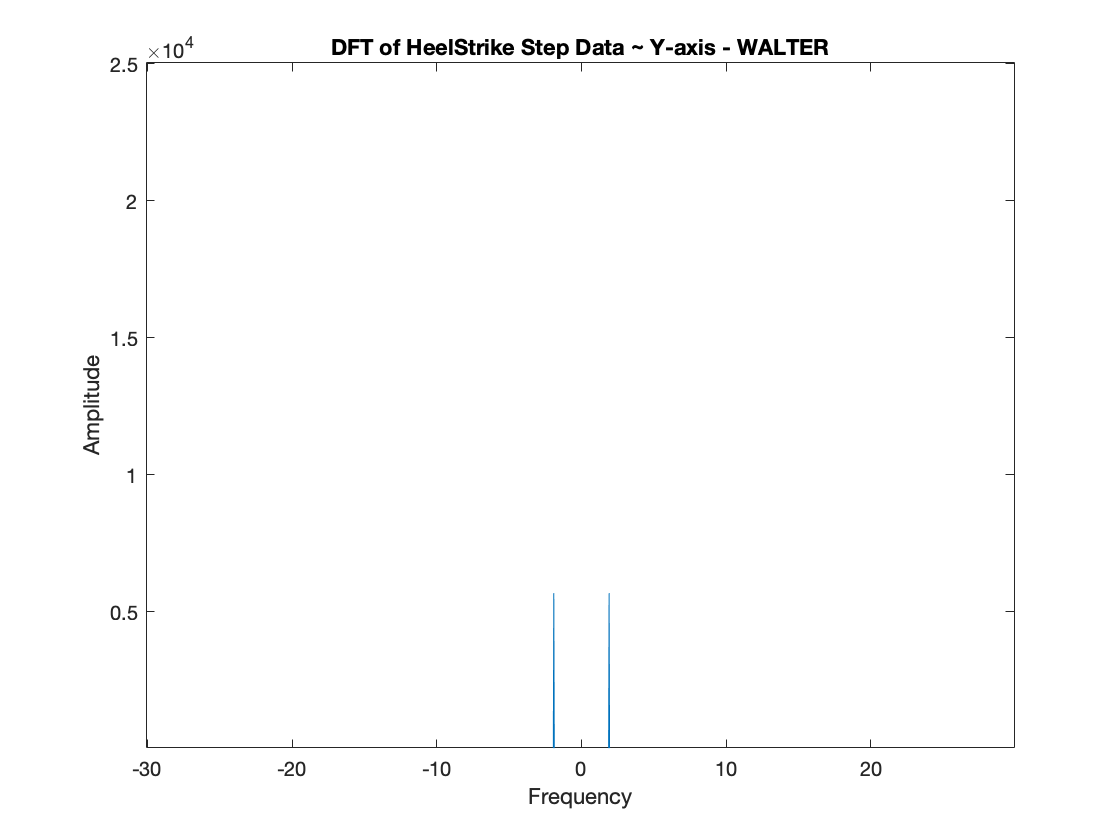


% Algorithm used to filter 

idx_mid_h = F_FINALheelstrike == 0;   % Finding Idex of when F_mid = 0
P_FINALheelstrike(idx_mid_h) = 0;     % Setting the value at that index = 0
maxi_h = max(abs(P_FINALheelstrike)); % Setting the next highest peaks to the max


% Looping to identify the peaks in our DFT
idx_max_h = F_FINALheelstrike == maxi_h;
for i = 1:length(P_FINALheelstrike)
    if abs(P_FINALheelstrike(i)) < maxi_h
        P_FINALheelstrike(i) = 0;
    end
end

% Plotting the DFT
plot(F_FINALheelstrike,abs(P_FINALheelstrike')) 
title("DFT of HeelStrike Step Data ~ Y-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");
xlim([-30.1 29.9])
ylim([22 25022])